# **Problem 1**

clear;

X = 0:.01:2;
Y = sin(2*pi*X)+.1*rand(size(X));

net = newff([0 2],[3 1],{'tansig' 'purelin'});

          See help for NEWFF to update calls to the new argument list.
 


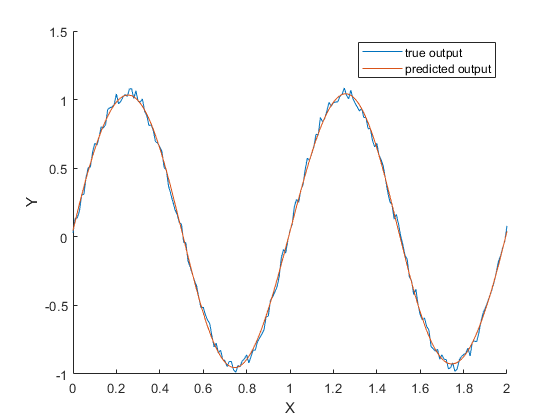



net.trainParam.epochs = 2000;
net.trainParam.goal = .001;       

net = train(net,X,Y);
simY = sim(net,X);

%caculate the root-mean-square of simulation result between true output and predicted output.
RMS = sqrt(mean((Y-simY).^2));

figure;
hold on;
plot(X,Y);
plot(X,simY);
xlabel('X'); 
ylabel('Y');
legend('true output','predicted output');
hold off;

在測試時於148 epochs 時收斂，但經多次測試可發現收斂所需的epoch數皆不同，且可能到最大值之2000 epochs 時仍未能收斂，同時能從simulation/true result圖上看出兩者落差。

# **Problem 2**

clear; 
addpath(strcat(pwd,'/CNN/CNN'));

%load the data
load('07HW2_digit.mat');
train_x = [train0;train1;train2;train3;train4;train5;train6;train7;train8;train9];
test_x = [test0;test1;test2;test3;test4;test5;test6;test7;test8;test9];
train_y = zeros(10,5000);
test_y = zeros(10,1000);
train_x = double(train_x)/256;
train_x = reshape(train_x',28,28,5000);
test_x = double(test_x)/256;
test_x = reshape(test_x',28,28,1000);

for i = 1:10
    train_y(i,(i-1)*500+1:i*500) = 1;
    test_y(i,(i-1)*100+1:i*100) = 1;
end

(a)

% Train
cnn.layers = {
    struct('type','i')                                    % input layer
    struct('type','c','outputmaps',6,'kernelsize',5)      % convolution layer
    struct('type','s','scale',2)                          % sub sampling layer
    struct('type','c','outputmaps',12,'kernelsize',5)     % convolution layer
    struct('type','s','scale',2)                          % subsampling layer
};
opts.alpha = 1;
opts.batchsize = 50;
opts.numepochs = 10;

rand('state',0);
cnn = cnnsetup(cnn,train_x,train_y);
cnn = cnntrain(cnn,train_x,train_y,opts);

epoch 1/10
Elapsed time is 4.332359 seconds.
epoch 2/10
Elapsed time is 4.367246 seconds.
epoch 3/10
Elapsed time is 4.248994 seconds.
epoch 4/10
Elapsed time is 4.289714 seconds.
epoch 5/10
Elapsed time is 4.444537 seconds.
epoch 6/10
Elapsed time is 4.454027 seconds.
epoch 7/10
Elapsed time is 4.305420 seconds.
epoch 8/10
Elapsed time is 4.324889 seconds.
epoch 9/10
Elapsed time is 4.348305 seconds.
epoch 10/10
Elapsed time is 4.389662 seconds.


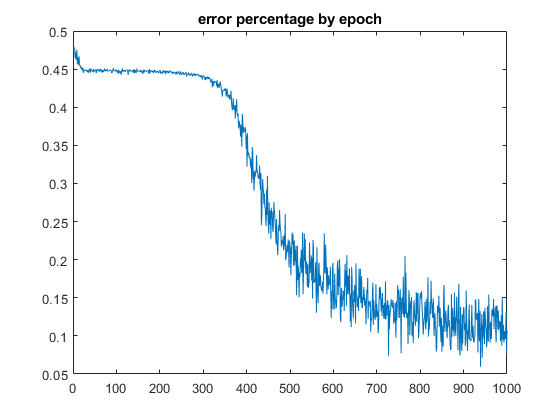

[ac_train,er_train,~] = cnntest(cnn,train_x,train_y);
[ac_test,er_test,~] = cnntest(cnn,test_x,test_y);
ac_train=ac_train*100;
ac_test=ac_test*100;
plot(cnn.train_rL);
title('error percentage by epoch');

fprintf('training accuracy = %s ％\ntesting accuracy = %s ％',num2str(ac_train),num2str(ac_test));

training accuracy = 87.24 ％
testing accuracy = 85.6 ％

(b)

% Train
cnn.layers = {
    struct('type','i')                                    % input layer
    struct('type','c','outputmaps',6,'kernelsize',5)      % convolution layer
    struct('type','s','scale',2)                          % sub sampling layer
    struct('type','c','outputmaps',12,'kernelsize',5)     % convolution layer
    struct('type','s','scale',2)                          % subsampling layer
};
opts.alpha = 2;
opts.batchsize = 25;
opts.numepochs = 200;

rand('state',0);
cnn = cnnsetup(cnn,train_x,train_y);
cnn = cnntrain(cnn,train_x,train_y,opts);

epoch 1/200
Elapsed time is 5.079867 seconds.
epoch 2/200
Elapsed time is 4.924916 seconds.
epoch 3/200
Elapsed time is 4.977884 seconds.
epoch 4/200
Elapsed time is 4.962669 seconds.
epoch 5/200
Elapsed time is 4.956975 seconds.
epoch 6/200
Elapsed time is 4.962768 seconds.
epoch 7/200
Elapsed time is 4.971759 seconds.
epoch 8/200
Elapsed time is 4.964933 seconds.
epoch 9/200
Elapsed time is 4.995959 seconds.
epoch 10/200
Elapsed time is 5.008319 seconds.
epoch 11/200
Elapsed time is 4.978508 seconds.
epoch 12/200
Elapsed time is 4.985697 seconds.
epoch 13/200
Elapsed time is 5.006583 seconds.
epoch 14/200
Elapsed time is 4.979490 seconds.
epoch 15/200
Elapsed time is 4.983494 seconds.
epoch 16/200
Elapsed time is 5.003034 seconds.
epoch 17/200
Elapsed time is 4.996647 seconds.
epoch 18/200
Elapsed time is 4.987711 seconds.
epoch 19/200
Elapsed time is 5.009929 seconds.
epoch 20/200
Elapsed time is 5.000094 seconds.
epoch 21/200
Elapsed time is 4.988660 seconds.
epoch 22/200
Elapsed t

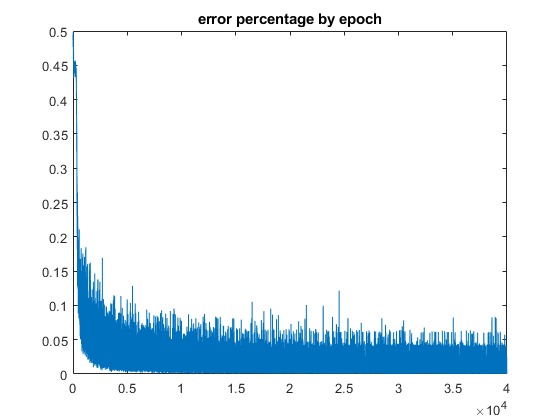

[ac_train,er_train,bad1] = cnntest(cnn,train_x,train_y);
[ac_test,er_test,bad2] = cnntest(cnn,test_x,test_y);
ac_train=ac_train*100;
ac_test=ac_test*100;
plot(cnn.train_rL);
title('error percentage by epoch');

fprintf('training accuracy = %s ％\ntesting accuracy = %s ％',num2str(ac_train),num2str(ac_test));

training accuracy = 99.14 ％
testing accuracy = 96.3 ％

由測試得到:

當 learning rate=1 , batch size=50, number of epochs=10時，training accuracy =87.24%  ;testing accuracy =85.60%

當 learning rate=1 , batch size=50, number of epochs=20時，training accuracy 91.84%  ;testing accuracy =89.80%

當 learning rate=1 , batch size=25, number of epochs=10時，training accuracy 91.64%  ;testing accuracy =89.80%

當 learning rate=2 , batch size=50, number of epochs=10時，training accuracy =89.72%  ;testing accuracy =88.00%

當 learning rate=2 , batch size=25, number of epochs=10時，training accuracy =93.56%  ;testing accuracy =92.20%

當 learning rate=2 , batch size=25, number of epochs=100時，training accuracy =98.76%  ;testing accuracy =96.20%

當 learning rate=2 , batch size=25, number of epochs=200時，training accuracy =99.14%  ;testing accuracy =96.30%

當 learning rate=2 , batch size=25, number of epochs=300時，training accuracy =99.28%  ;testing accuracy =96.50%

因此可發現當 learning rate=2 , batch size=25, number of epochs=100時，testing accuracy已接近測得知最佳值，當number of epochs調高至200時，accuracy僅微幅增加。

其中 number of epochs 對accuracy影響最大。

(c)

accuracy of SVM classifier (RBF kernal)=98.73%，較CNN classifier高。

在訓練過程中，SVM透過尋找hyper plane使資料能有效分類，而CNN則是透過卷積神經網路學習資料的特徵。